# 路径应力后处理

%y方向
[~,ia] = unique(y_axis_7105(:,1));
[~,ia2] = unique(y_hoop_7105(:,1));
YY = linspace(min(y_axis_7105(ia,1)),max(y_axis_7105(ia,1)),100)';
Y_axis_s = interp1(y_axis_7105(ia,1),y_axis_7105(ia,2),YY,'spline');
Y_hoop_s = interp1(y_hoop_7105(ia2,1),y_hoop_7105(ia2,2),YY,'spline');
%x方向
[~,ia] = unique(x_axis_7105(:,1));
[~,ia2] = unique(x_hoop_7105(:,1));
XX= linspace(min(x_axis_7105(ia,1)),max(x_axis_7105(ia,1)),100)';
X_axis_s = interp1(x_axis_7105(ia,1),x_axis_7105(ia,2),XX,'spline');
X_hoop_s = interp1(x_hoop_7105(ia2,1),x_hoop_7105(ia2,2),XX,'spline');

## 绘图

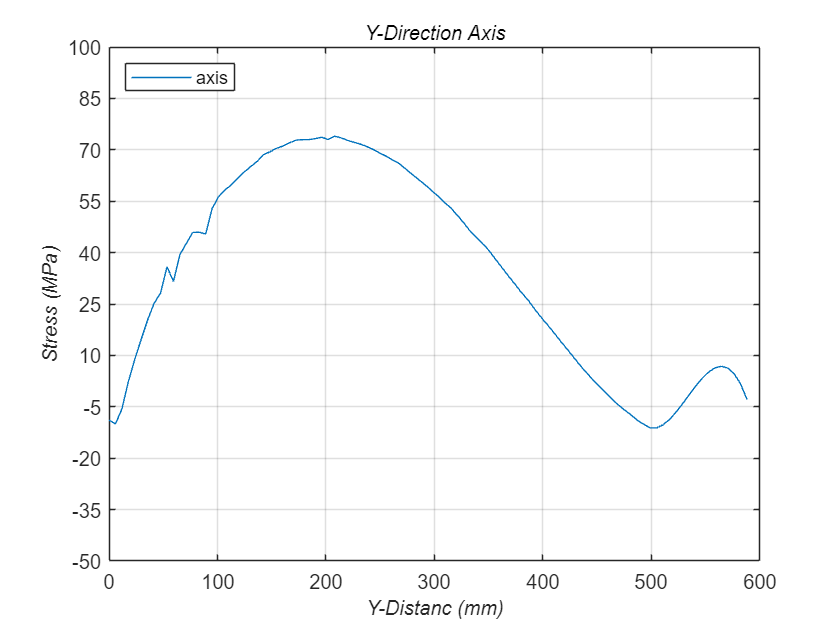

%hoop
figure(1)
plot(YY,Y_axis_s);
grid on
xlabel('Y-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('axis')
set(legend,'Location','NorthWest');
ylim([-50,100]);
yticks(-50:15:100);
title('Y-Direction Axis','fontsize',10,"FontAngle","italic")

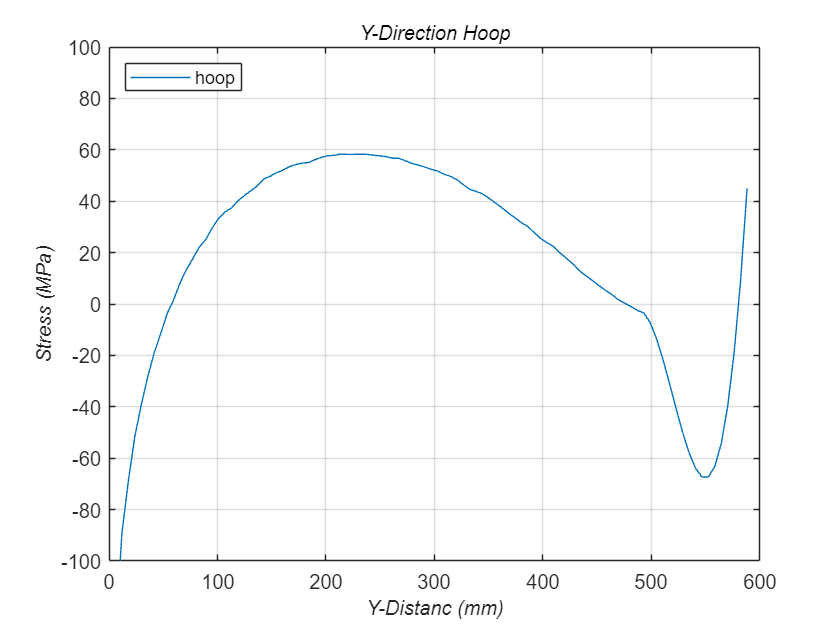

figure(2)
plot(YY,Y_hoop_s);
grid on
xlabel('Y-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('hoop')
set(legend,'Location','NorthWest');
ylim([-100,100]);
yticks(-100:20:100);
title('Y-Direction Hoop','fontsize',10,"FontAngle","italic")

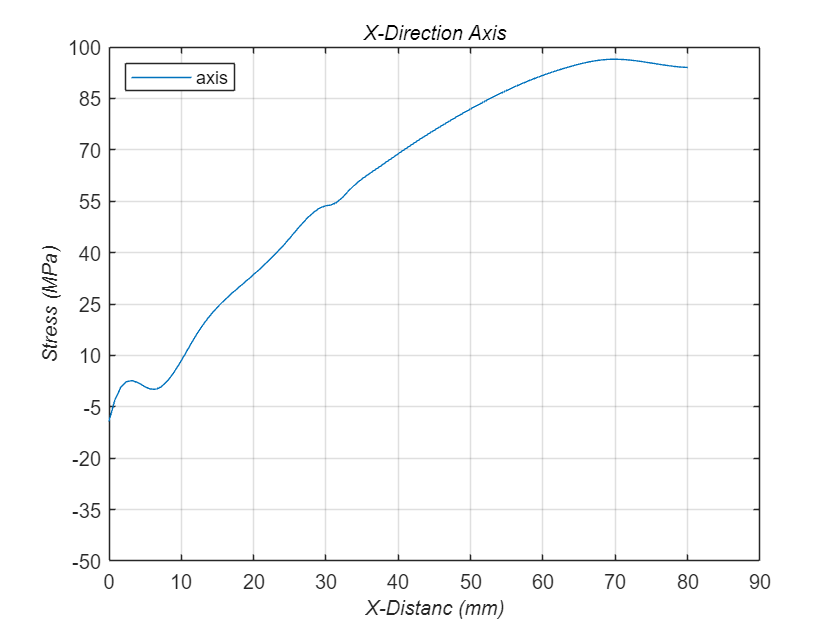


%aixs
figure(3)
plot(XX,X_axis_s);
grid on
xlabel('X-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('axis')
set(legend,'Location','NorthWest');
ylim([-50,100]);
yticks(-50:15:100);
title('X-Direction Axis','fontsize',10,"FontAngle","italic")

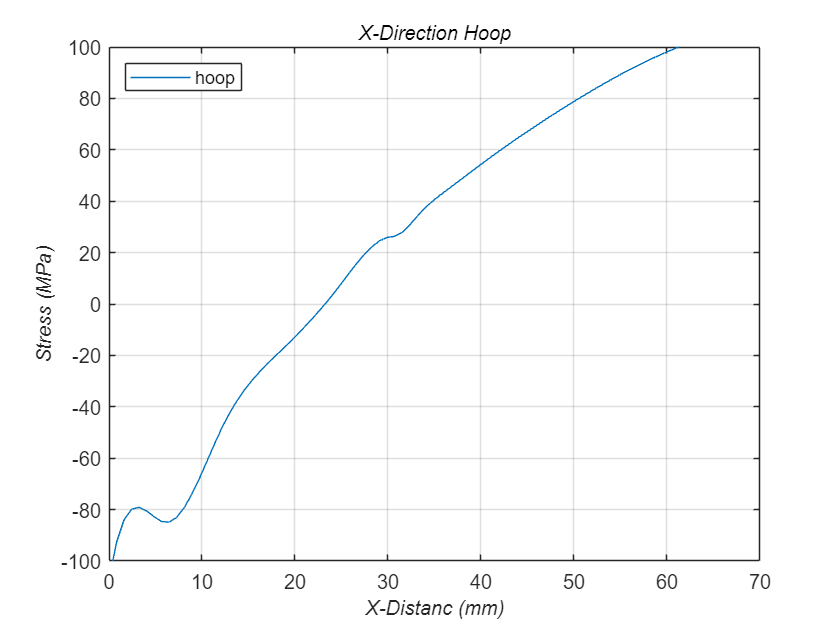

figure(4)
plot(XX,X_hoop_s);
grid on
xlabel('X-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('hoop')
set(legend,'Location','NorthWest');
ylim([-100,100]);
yticks(-100:20:100);
title('X-Direction Hoop','fontsize',10,"FontAngle","italic")


% figure(3)
% h = plot([YY,YY],[Y_axis_s,Y_hoop_s],'MarkerFaceColor','auto');
% set(h, {'MarkerFaceColor'}, get(h,'Color'));
% grid on
% xlabel('Y-Distanc (mm)','fontsize',10,"FontAngle","italic");
% ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
% legend('axis','hoop','Orientation','horizontal')
% set(legend,'Location','NorthWest');
% ylim([-100,100]);
% yticks(-100:20:100);
% title('Y-Drection','fontsize',10,"FontAngle","italic")
% figure(4)
% h = plot([XX,XX],[X_axis_s,X_hoop_s],'MarkerFaceColor','auto');
% set(h, {'MarkerFaceColor'}, get(h,'Color'));
% grid on
% xlabel('X-Distanc (mm)','fontsize',10,"FontAngle","italic");
% ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
% legend('axis','hoop','Orientation','horizontal')
% set(legend,'Location','NorthWest');
% ylim([-100,100]);
% yticks(-100:20:100);
% title('X-Drection','fontsize',10,"FontAngle","italic")